% load datasets
netflix_data = readtable('netflix.csv');

hulu_data = readtable('hulu.csv');

prime_data = readtable('prime.csv');

## Histogram of Age Rating

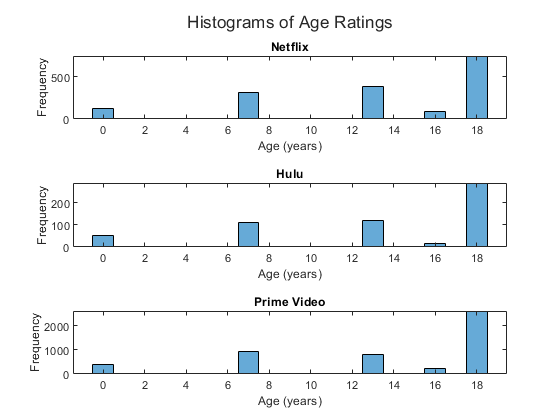

t = tiledlayout(3,1);
title(t,'Histograms of Age Ratings');

% netflix
nexttile;
age = netflix_data{:,3};
histogram(age)
title('Netflix');
xlabel('Age (years)');
ylabel('Frequency');

% hulu
nexttile;
age = hulu_data{:,3};
histogram(age)
title('Hulu');
xlabel('Age (years)');
ylabel('Frequency');

% prime
nexttile;
age = prime_data{:,3};
histogram(age)
title('Prime Video');
xlabel('Age (years)');
ylabel('Frequency');

## Histogram of IMDb rating

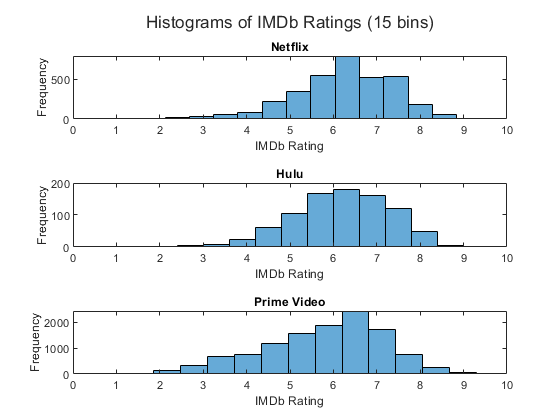

t = tiledlayout(3,1);
title(t,'Histograms of IMDb Ratings (15 bins)');
nbins = 15;

% netflix
nexttile;
imdbRating = netflix_data{:,4};
histogram(imdbRating,nbins)
title('Netflix');
xlabel('IMDb Rating');
ylabel('Frequency');
xlim([0 10]);
xticks(0:1:10);

% hulu
nexttile;
imdbRating = hulu_data{:,4};
histogram(imdbRating,nbins)
title('Hulu');
xlabel('IMDb Rating');
ylabel('Frequency');
xlim([0 10]);
xticks(0:1:10);

% prime
nexttile;
imdbRating = prime_data{:,4};
histogram(imdbRating,nbins)
title('Prime Video');
xlabel('IMDb Rating');
ylabel('Frequency');
xlim([0 10]);
xticks(0:1:10);

## Histogram of Rotten Tomatoes score

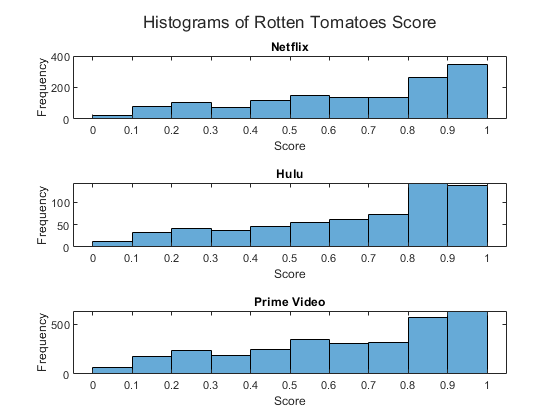

t = tiledlayout(3,1);
title(t,'Histograms of Rotten Tomatoes Score');

% netflix
nexttile;
rottenTomatoes = netflix_data{:,5};
histogram(rottenTomatoes)
title('Netflix');
xlabel('Score');
ylabel('Frequency');

% hulu
nexttile;
rottenTomatoes = hulu_data{:,5};
histogram(rottenTomatoes)
title('Hulu');
xlabel('Score');
ylabel('Frequency');

% prime
nexttile;
rottenTomatoes = prime_data{:,5};
nbins = 10;
histogram(rottenTomatoes,nbins)
title('Prime Video');
xlabel('Score');
ylabel('Frequency');

## Histogram of Runtime

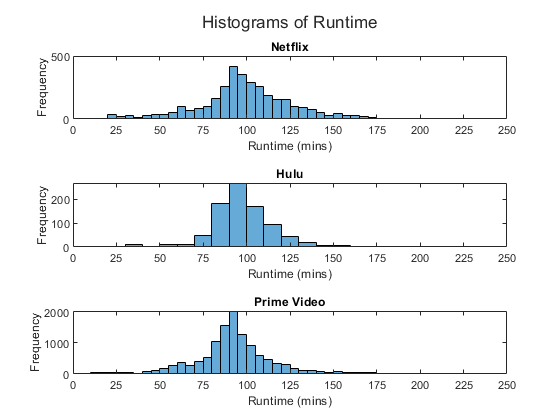

t = tiledlayout(3,1);
title(t,'Histograms of Runtime');

% netflix
nexttile;
runtime = netflix_data{:,10};
histogram(runtime);
title('Netflix');
xlabel('Runtime (mins)');
ylabel('Frequency');
xlim([0 250]);
xticks(0:25:250);

% hulu
nexttile;
runtime = hulu_data{:,10};
histogram(runtime);
title('Hulu');
xlabel('Runtime (mins)');
ylabel('Frequency');
xlim([0 250]);
xticks(0:25:250);

% prime
nexttile;
runtime = prime_data{:,10};
histogram(runtime);
title('Prime Video');
xlabel('Runtime (mins)');
ylabel('Frequency');
xlim([0 250]);
xticks(0:25:250);

## Histogram of Year

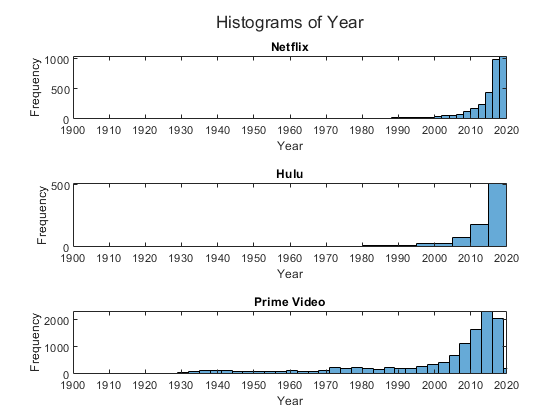

t = tiledlayout(3,1);
title(t,'Histograms of Year');

% netflix
nexttile;
year = netflix_data{:,2};
histogram(year);
title('Netflix');
xlabel('Year');
ylabel('Frequency');
xlim([1900 2020]);
xticks(1900:10:2020);

% hulu
nexttile;
year = hulu_data{:,2};
histogram(year);
title('Hulu');
xlabel('Year');
ylabel('Frequency');
xlim([1900 2020]);
xticks(1900:10:2020);

% prime
nexttile;
year = prime_data{:,2};
histogram(year);
title('Prime Video');
xlabel('Year');
ylabel('Frequency');
xlim([1900 2020]);
xticks(1900:10:2020);